clear; clf;
% All 1D arrays are column vectors

## System parameters

qpsk_bits_per_symbol = 2;
bpsk_bits_per_symbol = 1;
symbol_rate = 4800;

upsampling_factor = 32;
decimation_factor = 25;
downsampling_factor = 32;

RS_n = 255; 
RS_k = 223;

data_packet_size = 4*RS_k;
num_data_packets = 200;

EbN0dB = 0; 
no_paths = 3;

alpha = 0.4;
truncation_length = 10;

CC_polynomial_1 = [1 1 1 1 0 0 1];  % 171 in octal
CC_polynomial_2 = [1 0 1 1 0 1 1];  % 133 in octal
preamble = [1 1 1 0 1 1 1 1 0 0 0 1 0 1 1 0 1 1 1 0 0 1 0 1 1 0];

qpsk_constellation = [1+1i, 1-1i, -1+1i, -1-1i] / sqrt(2);
bpsk_constellation = [-1 1];
GF_LUT = 1; % unused

RS_coding = true;
CC_coding = true;

if RS_coding
    if CC_coding
        code_rate = 2*(RS_n/RS_k);
    else
        code_rate = (RS_n/RS_k);
    end
else
    if CC_coding
        code_rate = 2;
    else
        code_rate = 1;
    end
end


## Simulation

% ---- Transmitter ----
num_data_bits = data_packet_size*qpsk_bits_per_symbol*num_data_packets;
modulated_preamble = modulator(preamble, bpsk_bits_per_symbol, bpsk_constellation);

modulated_preamble_size = length(modulated_preamble);
coded_packet_size = code_rate*data_packet_size+modulated_preamble_size;

RRC_FIR_coefficients = 10*srrcGen_fullprecision(alpha, truncation_length, upsampling_factor, 'normalized');

uncoded_data_bits = bitGenerator(num_data_bits);

scrambled_bits = scrambler(uncoded_data_bits);

RS_encoded_bits = RSencoder(scrambled_bits, RS_n, RS_k, GF_LUT);

CC_encoded_bits = CCencoder(RS_encoded_bits, CC_polynomial_1, CC_polynomial_2);

modulated_symbols = modulator(CC_encoded_bits, qpsk_bits_per_symbol, qpsk_constellation);

framed_symbols = packetFraming(modulated_symbols, modulated_preamble, modulated_preamble_size, coded_packet_size);

pulseShaped_signal = polyphaseRRCfilter(framed_symbols, upsampling_factor, RRC_FIR_coefficients);

% plot(pulseShaped_signal)


% ---- Channel ----

freq_offset = (symbol_rate/(4))*(1 - 2*rand);
sampling_rate = symbol_rate*upsampling_factor;

[faded_signal, channel_taps] = ISIchannel(pulseShaped_signal, upsampling_factor, no_paths);

noisy_signal = addNoise(faded_signal, EbN0dB, upsampling_factor);

%rx_signal_with_fo = addFreqOffset(noisy_signal, freq_offset, sampling_rate);

agc_signal = automaticGainControl(faded_signal);

temp = round(2*coded_packet_size*upsampling_factor);
buffer_noise = 0.2*(randn(temp, 1) +1i*randn(temp, 1));

rx_signal = [buffer_noise; agc_signal; buffer_noise];
% rx_signal = [agc_signal];



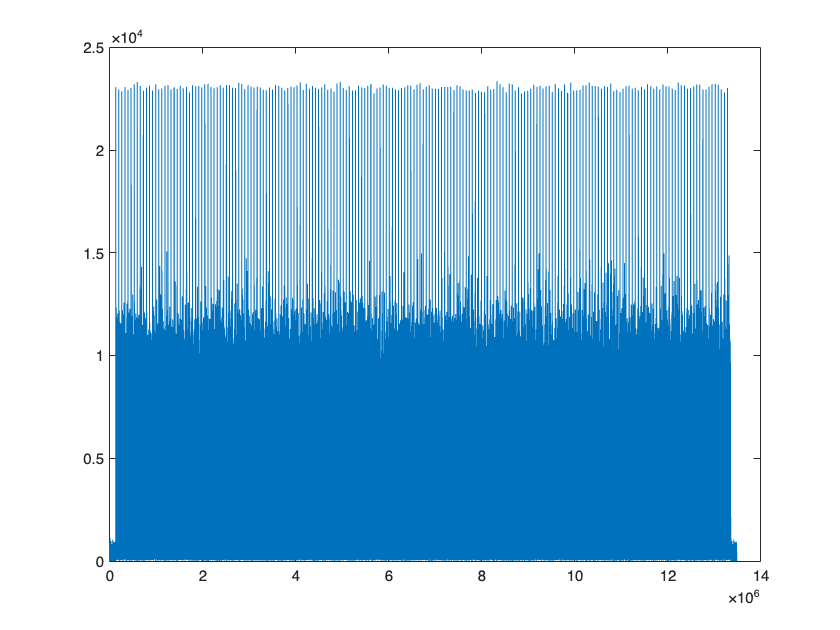

One packet extracted at 133696 and 2 more left in buffer
One packet extracted at 199808 and 2 more left in buffer
One packet extracted at 265920 and 2 more left in buffer
One packet extracted at 332031 and 2 more left in buffer
One packet extracted at 398143 and 2 more left in buffer
One packet extracted at 464256 and 2 more left in buffer
One packet extracted at 530368 and 2 more left in buffer
One packet extracted at 596480 and 2 more left in buffer
One packet extracted at 662591 and 2 more left in buffer
One packet extracted at 728704 and 2 more left in buffer
One packet extracted at 794815 and 2 more left in buffer
One packet extracted at 860928 and 2 more left in buffer
One packet extracted at 927040 and 2 more left in buffer
One packet extracted at 993152 and 2 more left in buffer
One packet extracted at 1059263 and 2 more left in buffer
One packet extracted at 1125375 and 2 more left in buffer
One packet extracted at 1191487 and 2 more left in buffer
One packet extracted at 1257

rx_synchronized_downsampled =    7.0794 - 2.7502i
  -2.6995 - 7.2973i
   6.6525 - 2.4893i
   7.0334 - 2.7181i
   7.2598 - 2.9236i
  -7.0833 + 2.4904i
  -2.8358 - 6.7588i
   6.9249 - 2.4308i
  -2.3422 - 7.5181i
  -7.4540 + 2.7631i


rx_pilot_synchronized_downsampled =   -3.1979 + 6.7602i
  -2.9222 + 6.8604i
  -3.1391 + 7.2227i
   3.5245 - 6.8546i
  -3.3977 + 6.4139i
  -3.0050 + 7.1107i
  -2.9189 + 6.7802i
  -3.1078 + 7.1490i
   3.4019 - 6.6015i
   2.9350 - 6.9760i



% ---- Receiver ----
threshold = 0.7*modulated_preamble_size*upsampling_factor;
samplingOffset = 0;
num_quantization_bits = 0; % for viterbi decoder
traceback_len = 35;

RRC_symbol_span = truncation_length;
rx_sampling_factor = downsampling_factor; % Downsampling factor to get Nyquist-rate samples
offset = rx_sampling_factor*(RRC_symbol_span + modulated_preamble_size);
data_sampling_range = rx_sampling_factor*((-RRC_symbol_span:1:(code_rate*data_packet_size-RRC_symbol_span-1)));
pilot_sampling_range = -offset:rx_sampling_factor:-rx_sampling_factor*(RRC_symbol_span + 1);

MF_FIR_coefficients = 2*srrcGen_fullprecision(alpha, truncation_length, downsampling_factor, 'normalized');

%[~, d] = lowpass(zeros(100,1), 1/decimation_factor,'Steepness',0.95);
%Dec_FIR_coefficients = d.Coefficients;

%rx_decimated = polyphaseDecimator(rx_signal, decimation_factor, Dec_FIR_coefficients);
%[fo_corrected_signal, freq_det] = freqOffsetCorrection(rx_signal_with_fo, symbol_rate*upsampling_factor);

rx_match_filtered = matchedFilter(rx_signal, MF_FIR_coefficients);
matched_preamble = matchedFilter(matchedFilter(upsample(modulated_preamble, upsampling_factor), MF_FIR_coefficients), MF_FIR_coefficients);

[rx_synchronized_downsampled , rx_pilot_synchronized_downsampled] = rxTimeSync(rx_match_filtered, flipud(matched_preamble), coded_packet_size*upsampling_factor, 10/3, 10, data_sampling_range, pilot_sampling_range, offset)

channel_est = channelEstimatorModified(rx_pilot_synchronized_downsampled, modulated_preamble_size, 3)

channel_est =   -3.2518 + 6.8892i
   0.1860 + 0.2755i
   0.0064 - 0.1195i


channel_taps

channel_taps =   -0.4265 + 0.9036i
   0.0390 + 0.0066i
  -0.0034 - 0.0062i


% equalized_symbols_1 = hard_decision_qpsk_viterbi_equalizer(rx_synchronized_downsampled, coded_packet_size, channel_taps, preamble, 15);
rx_equalized = soft_output_qpsk_viterbi_equalizer(rx_synchronized_downsampled, coded_packet_size, channel_taps, preamble, 15)

rx_equalized =   -5.5048 - 5.2338i
  -5.3063 + 5.2906i
  -5.4017 - 5.0893i
  -5.3160 - 5.4081i
  -5.6450 - 5.5677i
   5.3745 + 5.0760i
  -5.0927 + 5.7176i
  -5.3751 - 5.3672i
  -5.6404 + 5.1180i
   5.3726 + 5.4096i




% % Hard decoding
% detectedBitsReal = real(rx_synchronized_downsampled_v2) < 0; % 1 if real part is negative, 0 otherwise
% detectedBitsImag = imag(rx_synchronized_downsampled_v2) < 0; % 1 if imaginary part is negative, 0 otherwise
% 
% % Combine the real and imaginary parts to get the detected bits
% % detectedBits = [detectedBitsReal detectedBitsImag];
% detectedBits = reshape([detectedBitsReal, detectedBitsImag].', [], 1);
% % Reshape the detected bits to match the original format

CC_decoded_bits = ViterbiDecoder_qpsk(rx_equalized, traceback_len, CC_polynomial_1, CC_polynomial_2, qpsk_constellation, num_quantization_bits);
RS_decoded_bits = RSdecoder(CC_decoded_bits, RS_n, RS_k, GF_LUT);

descrambled_bits = descrambler(RS_decoded_bits);

% 
% 
% 
% ---- Performance computation ---- 
% before_decoding_errors = sum(detectedBits ~= CC_encoded_bits);
errors = sum(uncoded_data_bits ~= descrambled_bits);
ber = errors/length(uncoded_data_bits);
fprintf('\n%g errors and %g BER at %g Eb/N0 dB\n', errors, ber, EbN0dB);

0 errors and 0 BER at 0 Eb/N0 dB


% 
% 
% 
